# Covariates in regression analyses

This script simulates some common situations related to linear regression and explores power and effects.

Notation: 

**e** = error variable, simulates measurement error that cannot be explained by any predictor

**xs, ys, cs: *s "signal **variables" indicate latent variables of theoretical interest (without measurement noise). These are never directly observable

**x, y, c:** single-letter variables are measured variables. These are the observed variables that one can measure and include in regression models. ingle-letter variables 

-> indicates a causal effect

Variables with no *e are noiseless.

### Controlling on an covariate unrelated to outcome but related to predictor; c contributes to true x signal

Here, xs is a mediator of cs -> y, and controlling for c weakens the xs -> y relationship

Simplified model (assuming all measured variables have measurement error, so omitting *e:

c is related only to x.  x is related only to y.

%  x -> y
%  ^
%  |
%  c
%

Underlying model:

% xe                ye
%  |                |
%  v                v
%  x <- xs -> ys -> y
%       ^
%       |
%  c <- cs
%  ^
%  |
%  ce
%

% true
n = 1000;
clear d      % effect sizes
iter = 100;

for i = 1:iter

    % error
    ye = randn(n, 1); % y error
    xe = randn(n, 1); % x error
    ce = randn(n, 1); % c error

    % true causal signals
    cs = randn(n, 1);              % c true signal
    xs = randn(n, 1) + cs;  % x true signal (c contributes)
    ys = randn(n, 1) + xs;  % y true signal (c, x contribute)

    % observed signals: plus random noise (e)
    y = (ys + ye); % y observed (c does not contribute)
    x = (xs + xe); % x observed
    c = (cs + ce);

    % Fit with c
    [betas, dev, stats] = glmfit([x c], y);
    if i < 2, glm_table(stats, {'x' 'c'}); end
    tval = stats.t(2);
    d(i, 1) = tval ./ sqrt(n);

    % Fit without c
    [betas, dev, stats] = glmfit(x, y);
    if i < 2, glm_table(stats, {'x'}); end
    tval = stats.t(2);
    d(i, 2) = tval ./ sqrt(n);

end

        Name            Beta          SE           t            p           Sig  
    _____________    __________    ________    _________    __________    _______

    {'Intercept'}    -0.0042295    0.051282    -0.082475       0.93429    {' '  }
    {'x'        }        0.6006    0.031424       19.113    1.2673e-69    {'***'}
    {'c'        }       0.16543    0.039765       4.1602    3.4541e-05    {'***'}



        Name            Beta          SE          t            p           Sig  
    _____________    __________    ________    ________    __________    _______

    {'Intercept'}    -0.0080107    0.051691    -0.15497       0.87688    {' '  }
    {'x'        }       0.65292    0.029033      22.489    6.2055e-91    {'***'}



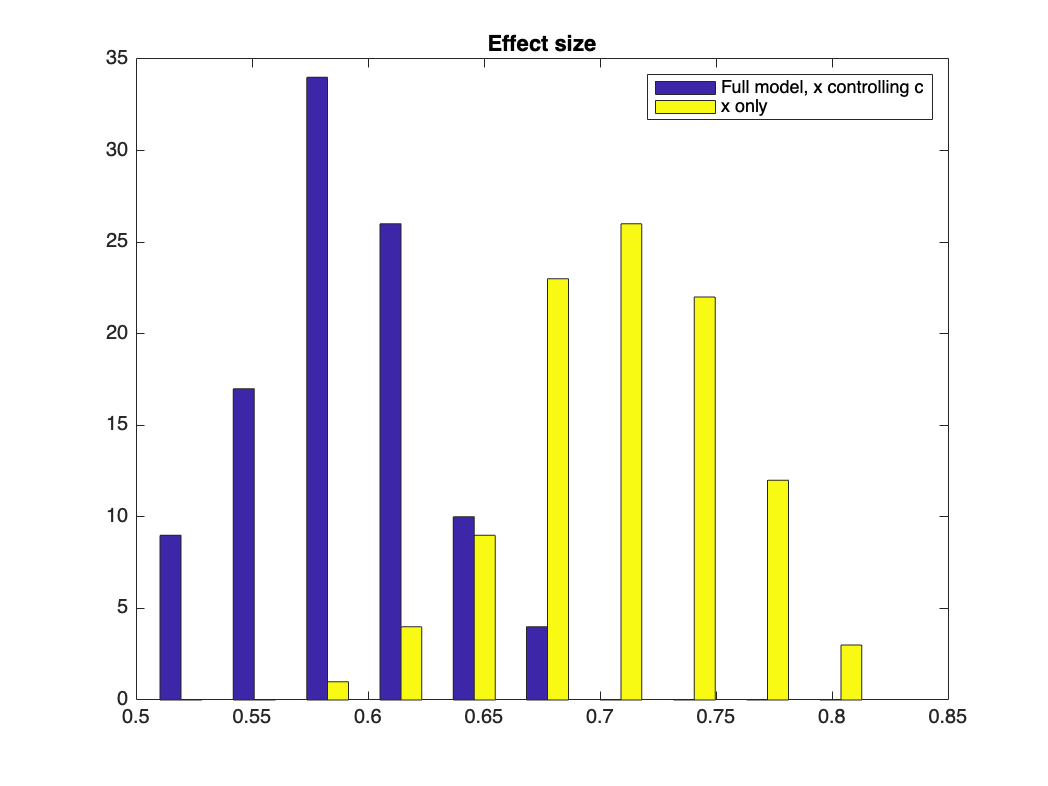


figure; hist(d); legend({'Full model, x controlling c', 'x only'}); title('Effect size')

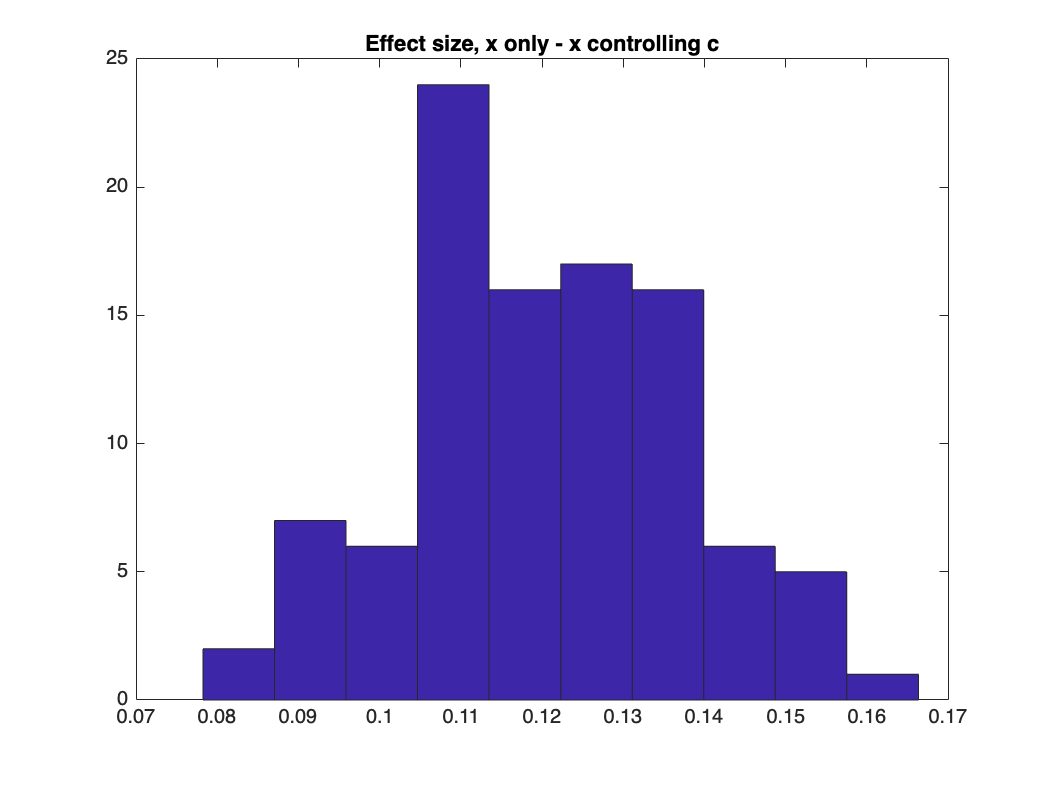

figure; hist(d(:, 2) - d(:, 1)); title('Effect size, x only - x controlling c');

## Controlling on an covariate unrelated to outcome but related to predictor, c contributes to true x signal

Here, xs is a mediator of cs -> y, and controlling for c weakens the xs -> y relationship

Simplified model (assuming all measured variables have measurement error, so omitting *e:

c is related only to x.  x is related only to y.

%     b
%   x -> y
%   ^
% a |
%   c
%

% true
n = 1000;
clear d      % effect sizes
iter = 100;

a = 1;
b = 1;
sigma = 1;

[d, c, x, y] = effect_sizes_c_causes_x_only(iter, a, b, sigma, n);

        Name           Beta         SE          t           p           Sig  
    _____________    ________    ________    _______    __________    _______

    {'Intercept'}    0.021306    0.034344    0.62037       0.53515    {' '  }
    {'x'        }     0.33031    0.028208      11.71    9.1265e-30    {'***'}
    {'c'        }     0.31728    0.027977     11.341    3.9975e-28    {'***'}

        Name           Beta         SE          t           p           Sig  
    _____________    ________    ________    _______    __________    _______

    {'Intercept'}    0.024814    0.036473  

d =     0.3709    0.5833
    0.3613    0.5686
    0.3407    0.5790
    0.3748    0.5857
    0.3963    0.6127
    0.3838    0.6089
    0.3528    0.5859
    0.3646    0.5820
    0.3440    0.5613
    0.3284    0.5553


c =     0.6909
    0.3901
    0.9828
   -0.3361
    3.6266
   -0.3524
    1.0384
   -1.2099
    1.1607
    1.8272


x =    -0.4408
   -0.9713
    1.5438
    1.3387
    2.4050
    0.2831
   -0.3049
   -1.9971
    0.4457
    1.0405


y =     1.0356
   -0.0328
    0.3770
   -0.8566
    1.0456
   -1.7418
    0.3048
   -1.2097
   -1.3028
    2.7788



r = corr([c x y])

r =     1.0000    0.4977    0.5367
    0.4977    1.0000    0.4894
    0.5367    0.4894    1.0000


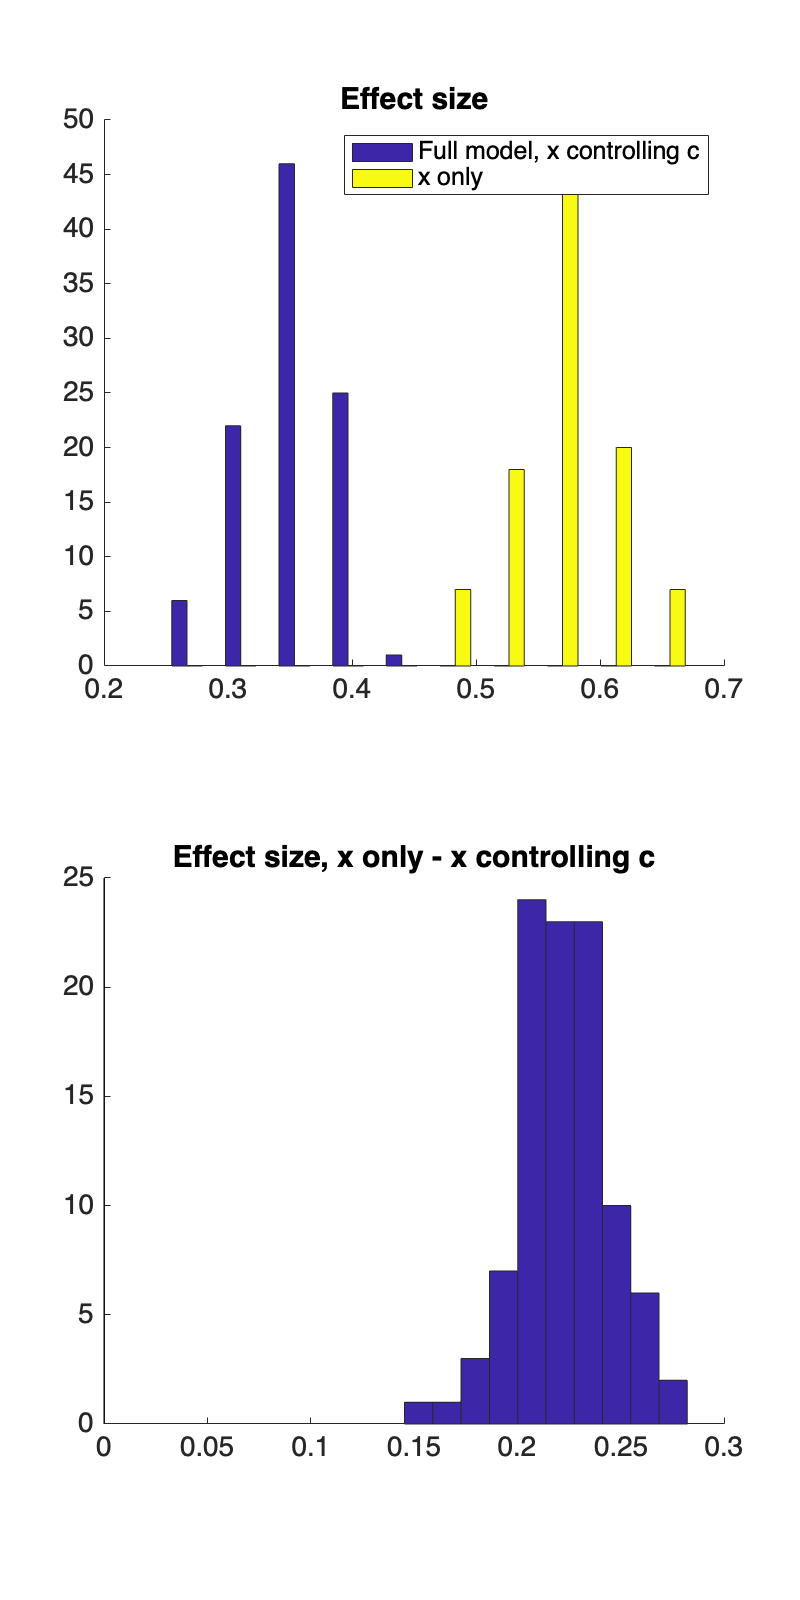


create_figure('histograms', 2, 1);
hist(d); legend({'Full model, x controlling c', 'x only'}); title('Effect size')

subplot(2, 1, 2)
hist(d(:, 2) - d(:, 1)); title('Effect size, x only - x controlling c');
plot_vertical_line(0);

disp('Pos = worse to control for c; Neg = better to control for c')

Pos = worse to control for c; Neg = better to control for c


## Controlling on an covariate unrelated to outcome but related to predictor, c contributes to x measurement noise not true x signal

Here, cs and xs are unrelated and c contributes a source of error to observed x.

 Controlling for c strengthens the xs -> y relationship.

 x is a "pseudo-mediator" here, because the cs->x effect and xs->y effects are actually independent.

c is not related to y, but appears to be a suppressor (significant negative relationship with y).

causal connections:

%     b
%   x -> y
%   ^
% a |
%   c
%

% xe
%  |
%  v
%  x <- xs -> ys -> y <- ye
%  ^
%  |
%  cs -> c
%        ^
%        |
%        ce

% true
n = 1000;
clear d      % effect sizes
iter = 100;

a = .5;
b = 1;
sigma = 1;

for i = 1:iter

    ye = sigma .* randn(n, 1); % y error
    xe = sigma .* randn(n, 1); % x error
    ce = sigma .* randn(n, 1); % c error

    cs = randn(n, 1);            % c true signal
    xs = randn(n, 1);            % x true signal (c does not contribute)
    ys = b .* xs;

    % observed signals: plus random noise (e)
    y = ys + ye;                    % y observed (c does not contribute)
    x = (xs + xe + a .* cs); % x observed
    c = cs + ce;

    % Fit with c
    [betas, dev, stats] = glmfit([x c], y);
    if i < 2, glm_table(stats, {'x' 'c'}); end
    tval = stats.t(2);
    d(i, 1) = tval ./ sqrt(stats.dfe);

    d_c(i, 1) = stats.t(3) ./ sqrt(stats.dfe);

    % Fit without c
    [betas, dev, stats] = glmfit(x, y);
    if i < 2, glm_table(stats, {'x'}); end
    tval = stats.t(2);
    d(i, 2) = tval ./ sqrt(stats.dfe);

    e = ys - x * betas(2); % prediction error (residuals)
    1 - (var(e) ./ var(ys)); % prediction r^2 var explained;


end

        Name           Beta         SE          t           p           Sig  
    _____________    ________    ________    _______    __________    _______

    {'Intercept'}    0.008996    0.039111    0.23001       0.81813    {' '  }
    {'x'        }     0.43353    0.027135     15.977    2.4923e-51    {'***'}
    {'c'        }    -0.10456    0.027518    -3.7998    0.00015357    {'***'}



        Name           Beta          SE          t           p          Sig  
    _____________    _________    ________    _______    _________    _______

    {'Intercept'}    0.0083838    0.039373    0.21294      0.83142    {' '  }
    {'x'        }      0.41065    0.026636     15.417    2.908e-48    {'***'}




create_figure('barplot');
barplot_columns([d d(:, 1) - d(:, 2) d_c], 'Effect sizes', 'nofigure', 'names', {'x cntrl c' 'x alone' 'diff(benefit of cntrl c)' 'c effect'});

Col   1: x cntrl c	Col   2: x alone	Col   3: diff(benefit of cntrl c)	Col   4: c effect	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
                Name                Mean_Value    Std_Error       T           P         Cohens_d
    ____________________________    __________    _________    _______    __________    ________

    {'x cntrl c'               }      0.55304     0.0033299     166.08    2.2204e-15     16.608 
    {'x alone'                 }      0.53329     0.0032598     163.59    2.2204e-15     16.359 
    {'diff(benefit of cntrl c)'}     0.019754     0.0010004     19.746    2.2204e-15     1.9746 
    {'c effect'                }     -0.12915     0.0033296    -38.787    2.2204e-15    -3.878

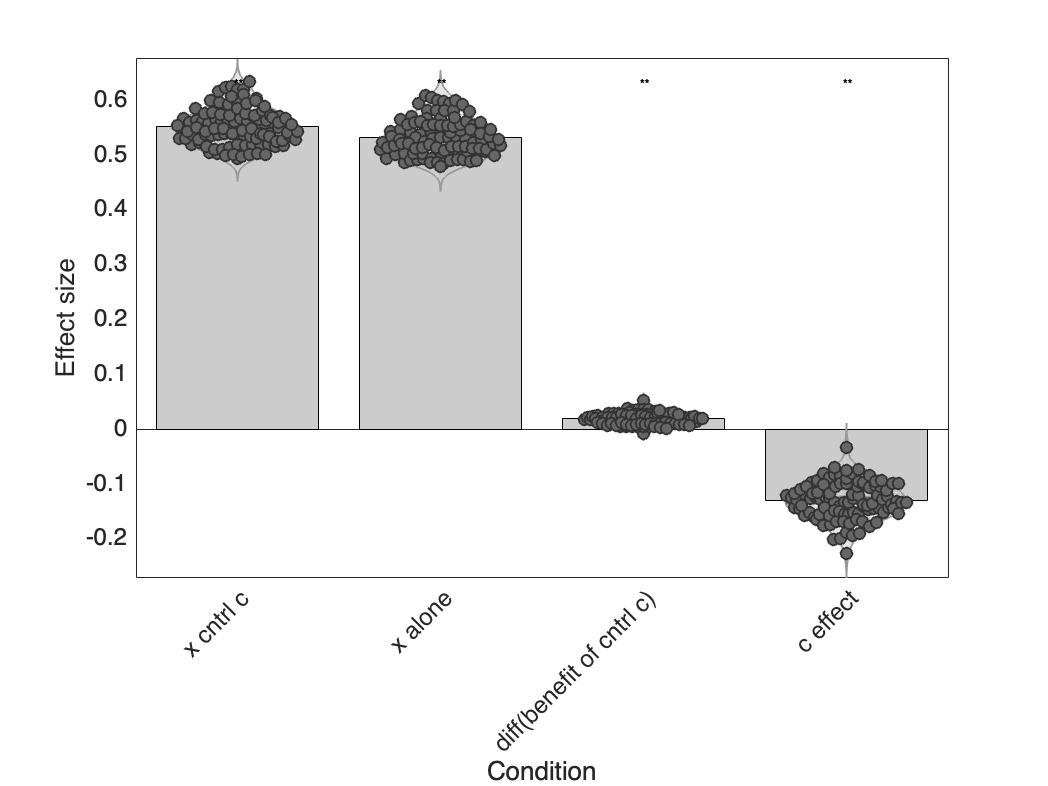

ylabel('Effect size');



% create_figure('histograms', 2, 1);
% hist(d); legend({'Full model, x controlling c', 'x only'}); title('Effect size')
%
% subplot(2, 1, 2)
% hist(d(:, 2) - d(:, 1)); title('Effect size, x only - x controlling c');
% plot_vertical_line(0);
% disp('Pos = worse to control for c; Neg = better to control for c')

### Increase or reduction in outcome var as a function of correlation with predicted

Adjusting for a predicted effect (effect of predictor or model x) may actually increase the variance (uncertainty) of an outcome variable (y), as the reduction due to x competes with the error variance induced by subtracting x.

Variance explained can only be positive within a training sample, but out of sample, it can be negative, resulting in a net increase in prediction error (negative variance explained here). Out of sample, the true relationship between x and y holds, but the true beta (slope) is unknown, and we must use a training sample to estimate it.

Prediction error: When you have a prediction from a model and intend to trust those scores, you don't get to subtract off a fraction (b) of the predicted response. Rather, you must look at the difference between actual and predicted. 

Conclusion: A predictor must explain half the variance in an outcome (r > 0.7) in order to actually increase the accuracy of predictions made using the predictor as a surrogate outcome.

%k = 10;     % Number of covariates
n = 20;     % Sample size - Training
ntest = 20; % sample size - Test
iter = 200; % Simulation iterations
%b = 1;      % True slope of x->y relationship
%sigma = 1;  % Noise std
int = ones(n, 1);

err = deal(NaN .* zeros(n, 1));
[var_exp_insample, var_exp_test, var_exp_pred] = deal(NaN .* zeros(n, iter));

rvals = [-.1:.01:1];  % correlation beween predicted and outcome

for i = 1:iter
    % for each iteration
    indx = 1;

    for r = rvals

        rvar = sign(r) .* r^2;
        dat = mvnrnd([0 0], [1 rvar; rvar 1], n);

        x = dat(:, 1);
        y = dat(:, 2);
        X = [x int];

        % Using x as a predictor, does it reduce var in y?
        var_exp_pred(indx, i) = 1 - (var(y - x) ./ var(y));

        b = pinv(X) * y;            % residuals
        err_in_sample = y - X * b;  % in-sample error (guaranteed var < var(y))

        % Variance explained when applying model (b) in-sample
        var_exp_insample(indx, i) = (var(y) - var(err_in_sample)) ./ var(y);

        % test sample
        dat_test = mvnrnd([0 0], [1 rvar; rvar 1], ntest);
        xt = dat_test(:, 1);
        yt = dat_test(:, 2);
        X_test = [xt int];

        err_test = yt - X_test * b;  % in-sample error (guaranteed var < var(y))

        % Variance explained when applying model (b) to new test sample
        var_exp_test(indx, i) = (var(yt) - var(err_test)) ./ var(yt);

        indx = indx + 1; % Loop var
    end

end % iterations

var_exp_pred_mean = mean(var_exp_pred, 2);
var_exp_insample_mean = mean(var_exp_insample, 2);
var_exp_test_mean = mean(var_exp_test, 2);

create_figure('Variance explained by x')

ans =   Figure (Variance explained by x) with properties:

      Number: 1
        Name: 'Variance explained by x'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


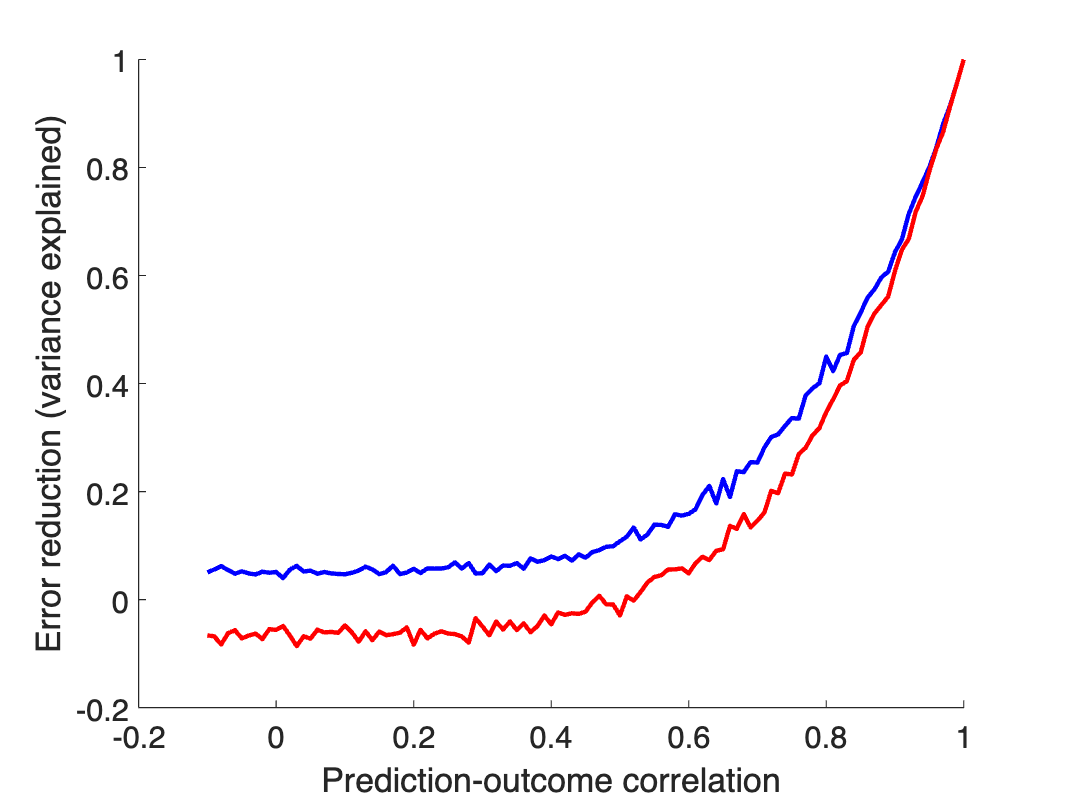

plot(rvals, var_exp_insample_mean, 'b-', 'LineWidth', 2);
plot(rvals, var_exp_test_mean, 'r-', 'LineWidth', 2);

xlabel('Prediction-outcome correlation')
ylabel('Error reduction (variance explained)')


create_figure('Variance explained using x as prediction')

ans =   Figure (Variance explained using x as prediction) with properties:

      Number: 4
        Name: 'Variance explained using x as prediction'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


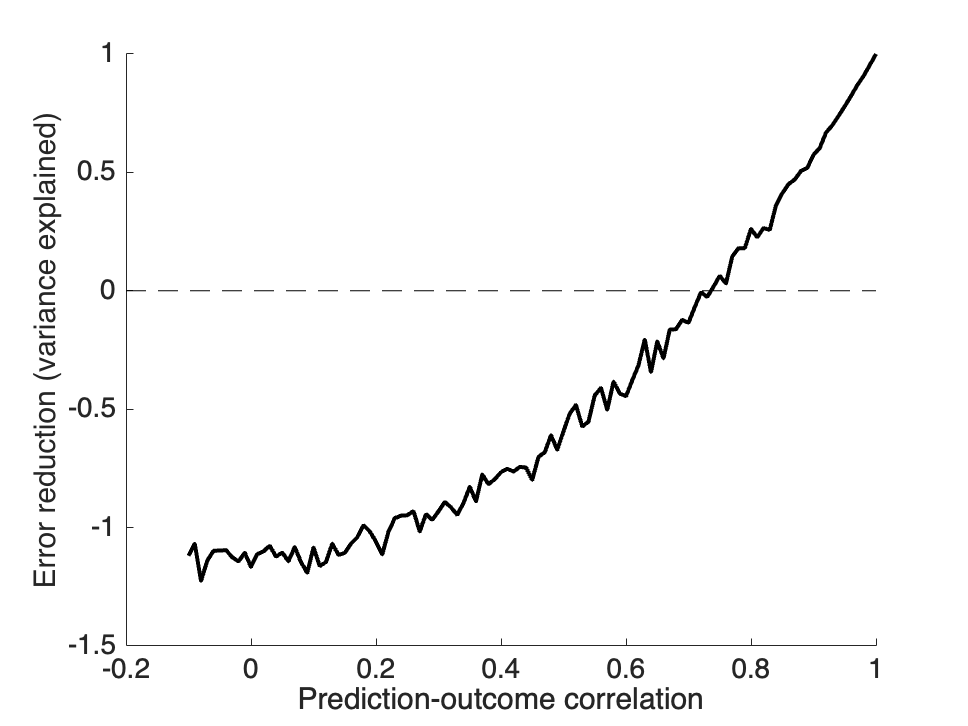

plot(rvals, var_exp_pred_mean, 'k-', 'LineWidth', 2);
xlabel('Prediction-outcome correlation')
ylabel('Error reduction (variance explained)')
hh = plot_horizontal_line(0);
set(hh, 'Linestyle', '--')

Conclusion: A predictor must explain half the variance in an outcome (r > 0.7) in order to actually increase the accuracy of predictions made using the predictor as a surrogate outcome.

### Power loss controlling for unrelated covariates

This is in progress - not right yet.  There is no diff in effect size controlling for unrelated covs. Can't just use effect size -- need to consider error and power. 

k = 10;     % Number of covariates

k = 10

n = 20;     % Sample size
iter = 100; % Simulation iterations
b = 1;      % True slope of x->y relationship
sigma = 1;  % Noise std

d = effect_sizes_c_is_unrelated(iter, b, sigma, n, k);
% b is true slope, sigma is noise std, n is sample size, k is num c variables
% c x y are examples from one iteration
% d has 3 columns: x controlling for c, x alone, and c(1) controlling for x


%     b
%   x -> y
%   ^
% 0 |
%   c
%

create_figure('barplot');
barplot_columns([d(:, 1:2) d(:, 1) - d(:, 2) d(:, 3)], 'Effect sizes', 'nofigure', 'names', {'x cntrl c' 'x alone' 'diff(benefit of cntrl c)' 'c effect'});

Col   1: x cntrl c	Col   2: x alone	Col   3: diff(benefit of cntrl c)	Col   4: c effect	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
                Name                Mean_Value     Std_Error        T            P          Cohens_d 
    ____________________________    ___________    _________    _________    __________    __________

    {'x cntrl c'               }        0.65612    0.042445        15.458    2.2204e-15        1.5458
    {'x alone'                 }         0.6565    0.024974        26.287    2.2204e-15        2.6287
    {'diff(benefit of cntrl c)'}    -0.00038017    0.033396     -0.011384       0.99094    -0.0011384
    {'c effect'                }       0.011998    0.041105        0.

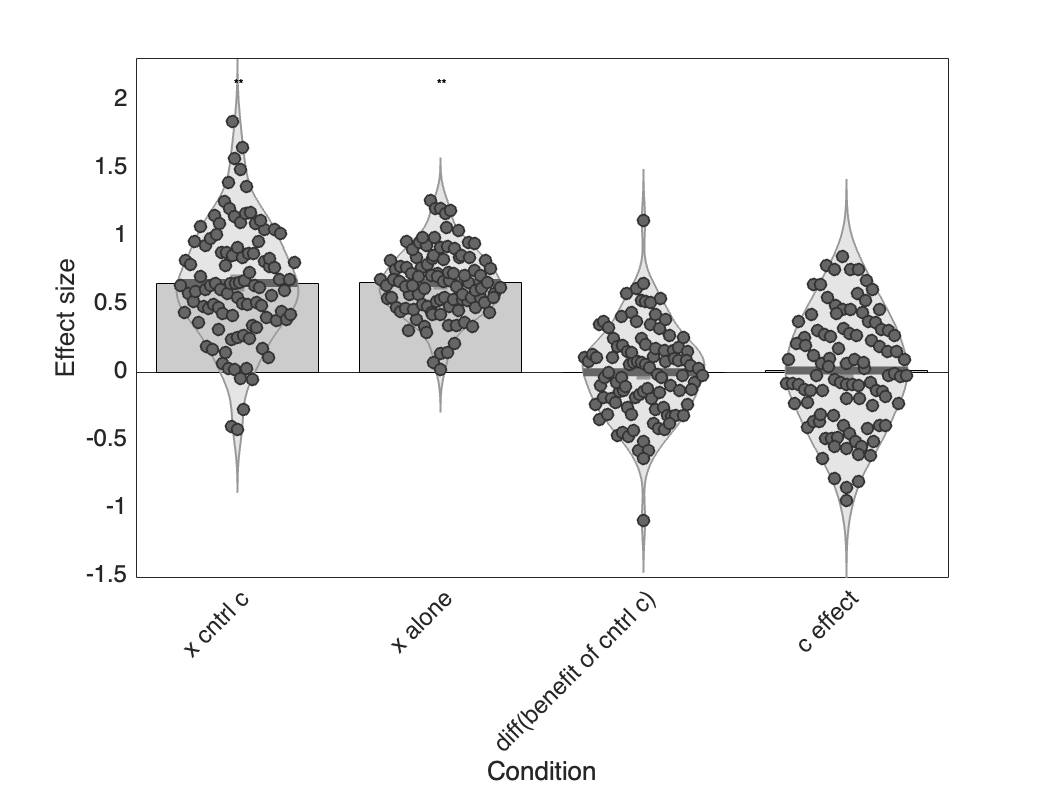

ylabel('Effect size');


create_figure('Power');
colors = custom_colors([.7 .5 .2], [1 .6 .2], 4);


dvals = mean(d(:, 1:2));

disp('x controlling for irrelevant covariate')

x controlling for irrelevant covariate


[ncrit,pow,obspow] = power_calc(dvals(1), .05, 20, 'd', 'b--', 0);

One sample: d = 0.66, N needed 80% =  16 , N needed 50% =   9

2-group: d = 0.66, N per group 80% =  31 , N per group 50% =  15





disp('x alone, no covariates')

x alone, no covariates


[ncrit,pow,obspow] = power_calc(dvals(2), .05, 20, 'd', 'r-', 0);

One sample: d = 0.66, N needed 80% =  16 , N needed 50% =   9

2-group: d = 0.66, N per group 80% =  31 , N per group 50% =  15



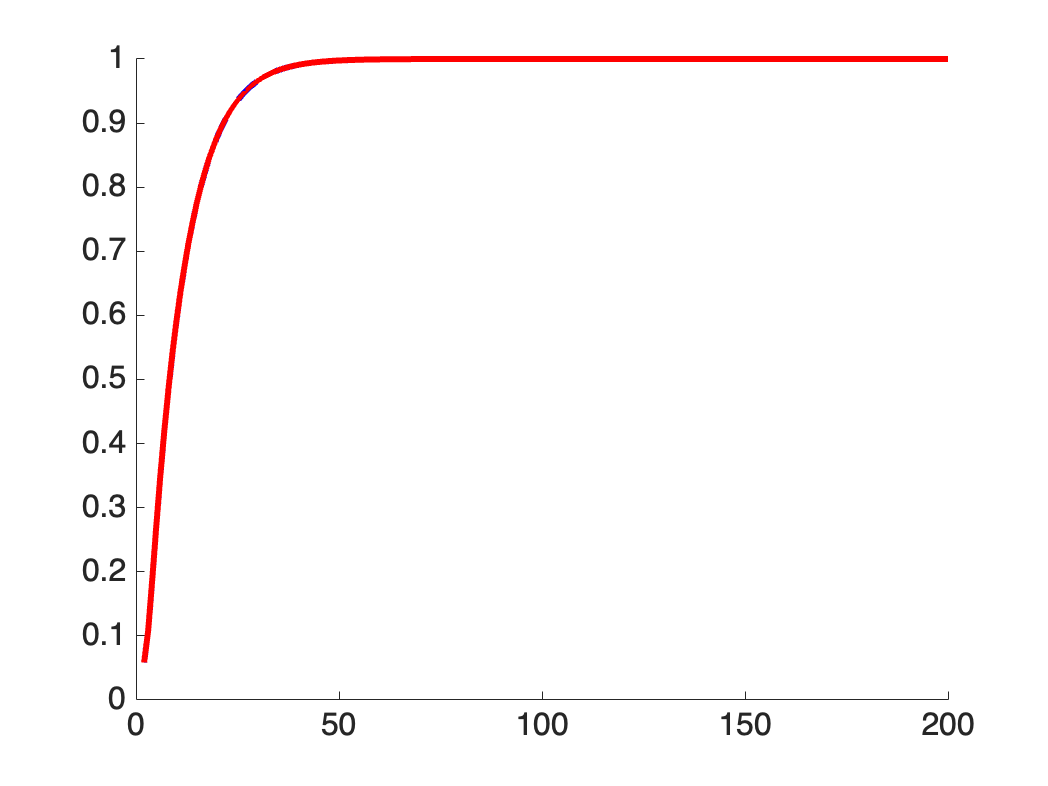


set(gca, 'XLim', [0 200]);


%   % axis limits
%   set(gca, 'XLim', [0 200]);
%   xlabel('N per group');
%   ylabel('Power')
%
%   % crosshairs (n is determined in advance)
%   hh = plot_vertical_line(99);
%   set(hh, 'LineStyle', '--', 'Color', [.2 .2 .2])
%   hh = plot_horizontal_line(.8);
%   set(hh, 'LineStyle', '--', 'Color', [.2 .2 .2])




causal connections:

## Conditioning on a collider

Here, c is a collider: A commmon effect of x and y.  

Let's say x is income, y is IQ, and c is the ranking of the school attended (higher in this example is better). A person can get into a high-ranked school (c) by either having a wealthy family or by doing well on an IQ test. So both are causal for attending a better school.  Let's further assume (and simulate) that income and IQ are unrelated in the general population.

Conditioning on school quality, the observed relationship between x and y (income and IQ) will be negative. This is a bias induced by controlling for (or conditioning on) c.  There are two different ways to be selected for the high-rank school group, so conditioning on school quality induces a negative correlation in the selected subpopulation.   

% c < y
% ^
% x

% true
n = 1000;

x = randn(n, 1);
y = randn(n, 1);
c = (x + y + randn(n, 1)) ./ 3;
int = ones(size(x));

[betas,~, r, ~, stats] = regress(y, [int c x]);

create_figure('scatter', 2, 2)

ans =   Figure (scatter) with properties:

      Number: 1
        Name: 'scatter'
       Color: [1 1 1]
    Position: [30 1087 893.6000 893.6000]
       Units: 'pixels'

  Show all properties


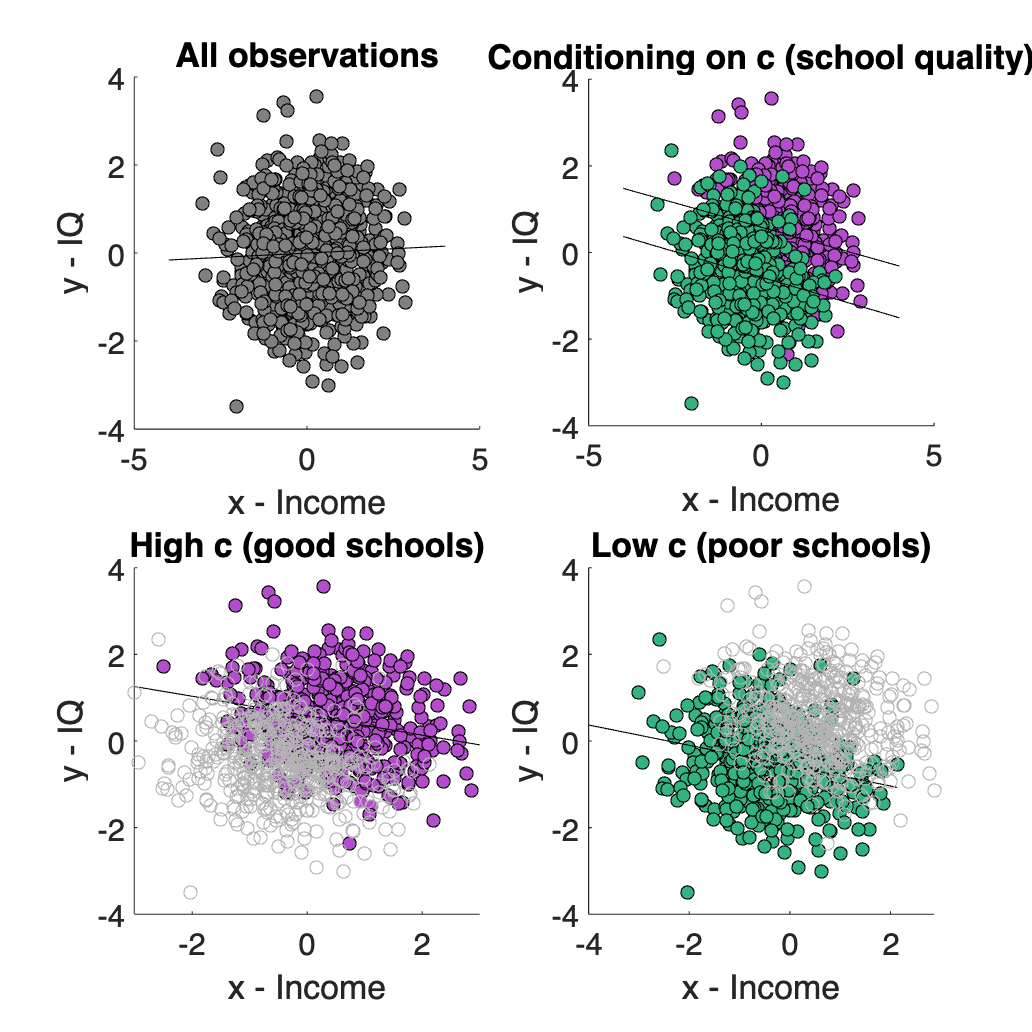


% All
plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('All observations')
refline

wh = c > median(c);

% Split - together
subplot(2, 2, 2)
% plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('Conditioning on c (school quality)')
refline

subplot(2, 2, 3)

plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
refline
plot(x(~wh), y(~wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('High c (good schools)')


subplot(2, 2, 4)

plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
refline
plot(x(wh), y(wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('Low c (poor schools)')

## Conditioning on a common cause

Now x and y are unrelated except for a common cause, c. 

A perfect test would thus find no direct effect of x on y after controlling for c. 

Here we observe no x -> y relationship, so controlling for c has worked as it should.  

disp('Conditioning on a common cause')

Conditioning on a common cause


% c > y
% v
% x

% true
n = 1000;

c = randn(n, 1);
x = (randn(n, 1) + c) ./ 2;
y = (randn(n, 1) + c) ./ 2;
% c = (x + y + randn(n, 1)) ./ 3;
int = ones(size(x));

[betas,~, r, ~, stats] = regress(y, [int c x]);

% the vector STATS contains, in
% the following order, the R-square statistic, the F statistic and p value
% for the full model, and an estimate of the error variance


A partial residual plot of x against y shows the null effect, as expected.

[b, dev, stats] = glmfit([x c], y);
glm_table(stats, {'x' 'c'}, b);

        Name           Beta          SE         t           p           Sig  
    _____________    _________    ________    ______    __________    _______

    {'Intercept'}    0.0077065    0.015818    0.4872       0.62623    {' '  }
    {'x'        }     0.029552    0.029944    0.9869       0.32393    {' '  }
    {'c'        }      0.49349    0.022004    22.427    1.6159e-90    {'***'}



If we binarize for display, we don't properly see the null effect. We have treated a continuous variable as categorical, and so have not properly controlled for c in this plot:

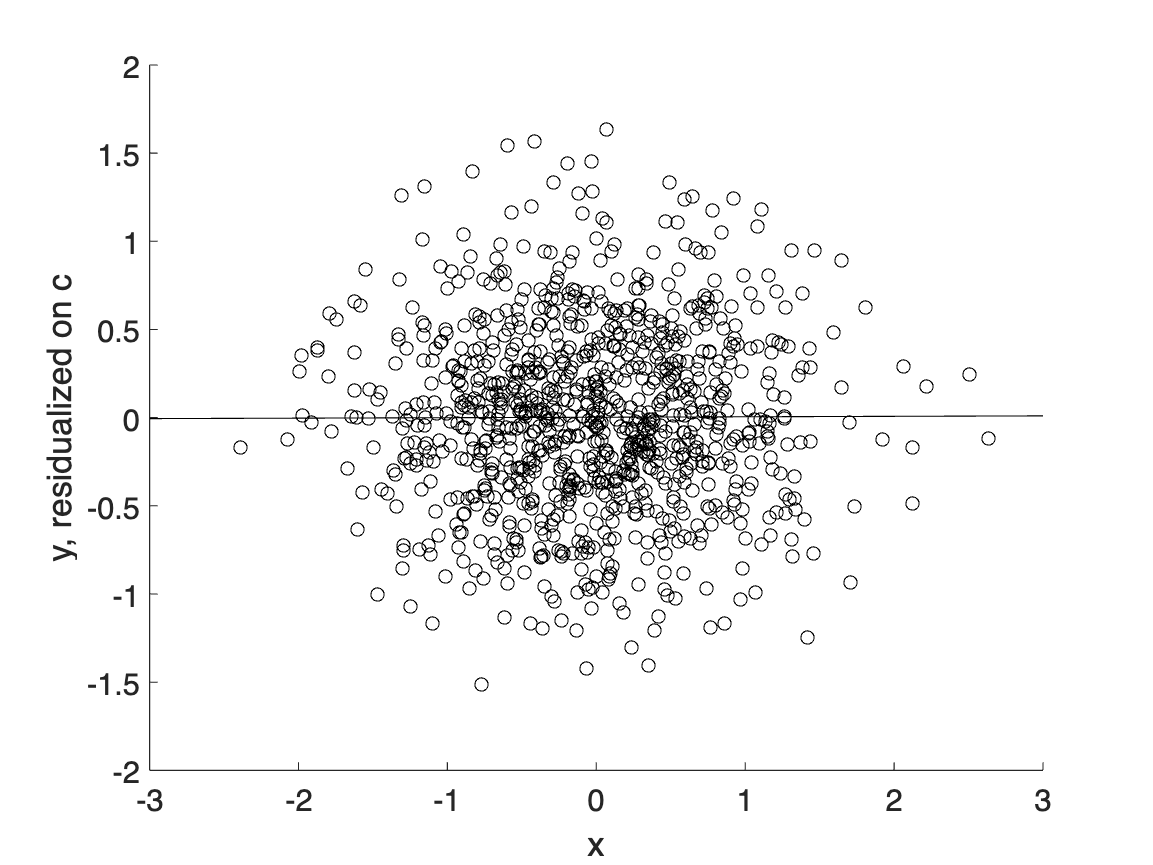

ans = 0.0037

create_figure('partial resid');
r = prplot(y, [x c], 1);

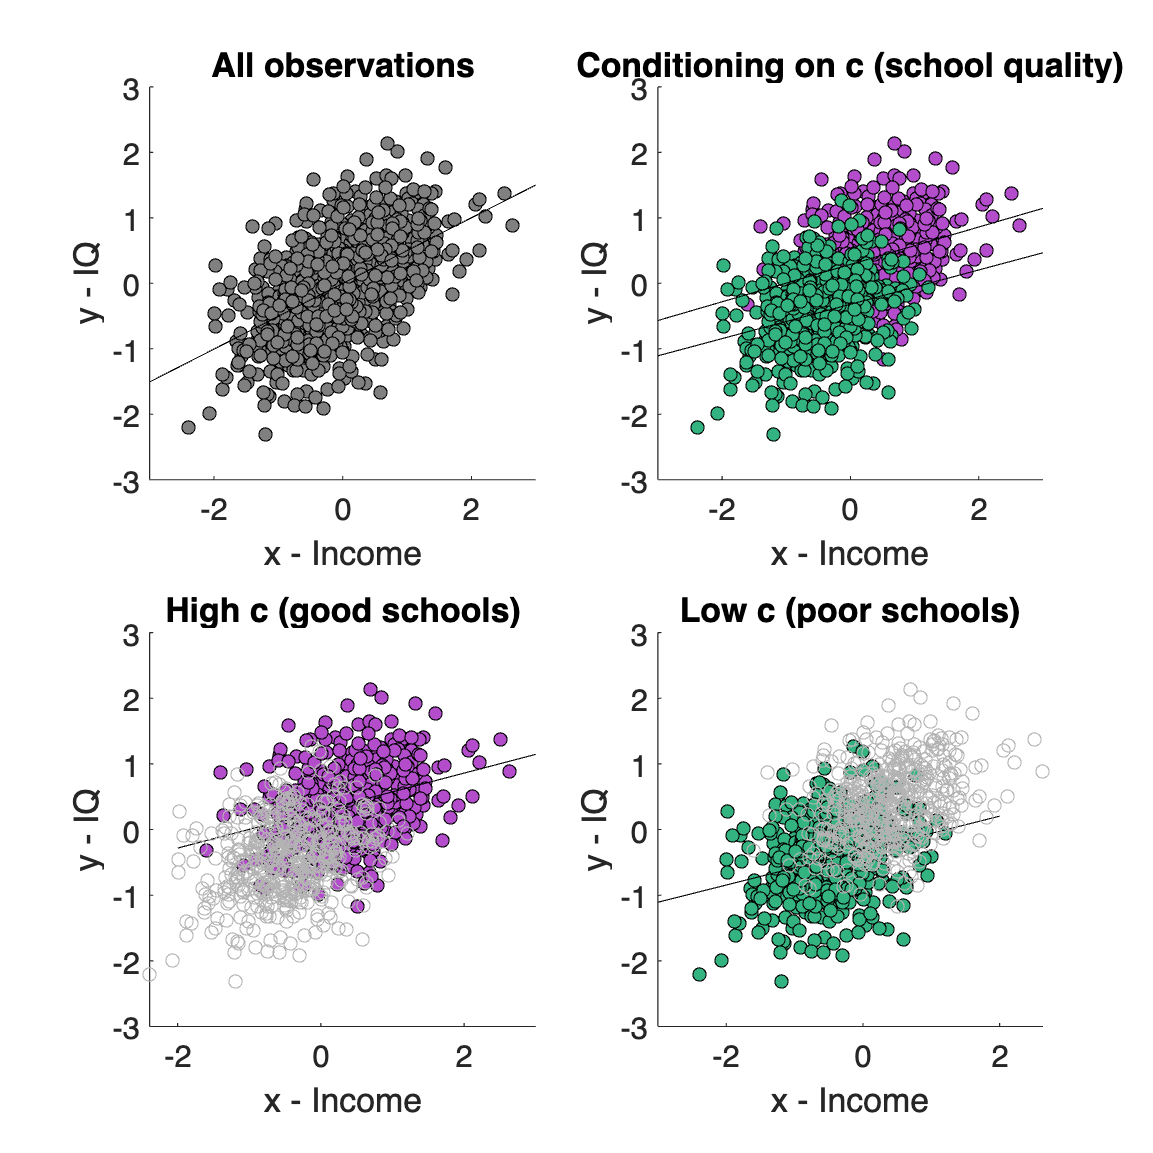

xlabel('x')
ylabel('y, residualized on c')



create_figure('scatter', 2, 2);

% All
plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('All observations')
refline

wh = c > median(c);


% Split - together
subplot(2, 2, 2)
% plot(x, y, 'ko', 'MarkerFaceColor', [.5 .5 .5]);
plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
xlabel('x - Income')
ylabel('y - IQ')
title('Conditioning on c (school quality)')
refline

subplot(2, 2, 3)

plot(x(wh), y(wh), 'ko', 'MarkerFaceColor', [.7 .3 .8]);
refline
plot(x(~wh), y(~wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('High c (good schools)')

subplot(2, 2, 4)

plot(x(~wh), y(~wh), 'ko', 'MarkerFaceColor', [.2 .7 .5]);
refline
plot(x(wh), y(wh), 'ko', 'Color', [.7 .7 .7]);

xlabel('x - Income')
ylabel('y - IQ')

title('Low c (poor schools)')

## Subfunctions

function [d, c, x, y] = effect_sizes_c_causes_x_only(iter, a, b, sigma, n)
% c x y are examples from one iteration

for i = 1:iter


    %     b
    %   x -> y
    %   ^
    % a |
    %   c
    %
    % error
    ye = sigma .* randn(n, 1); % y error
    xe = sigma .* randn(n, 1); % x error
    ce = sigma .* randn(n, 1); % c error

    % true causal signals
    cs = randn(n, 1);              % c true signal
    xs = a .* cs;  % x true signal (c contributes)
    ys = b .* xs;  % y true signal (c, x contribute)

    % observed signals: plus random noise (e)
    y = (ys + ye); % y observed (c does not contribute)
    x = (xs + xe); % x observed
    c = (cs + ce);

    % Fit with c
    [betas, dev, stats] = glmfit([x c], y);
    if i < 2, glm_table(stats, {'x' 'c'}); end
    tval = stats.t(2);
    d(i, 1) = tval ./ sqrt(stats.dfe);

    % Fit without c
    [betas, dev, stats] = glmfit(x, y);
    if i < 2, glm_table(stats, {'x'}); end
    tval = stats.t(2);
    d(i, 2) = tval ./ sqrt(stats.dfe);

end

end


function [d, c, x, y] = effect_sizes_c_is_unrelated(iter, b, sigma, n, k)
% b is true slope, sigma is noise std, n is sample size, k is num c variables
% c x y are examples from one iteration
% d has 3 columns: x controlling for c, x alone, and c(1) controlling for x

for i = 1:iter

    %     b
    %   x -> y
    %   ^
    % 0 |
    %   c
    %
    % error
    ye = sigma .* randn(n, 1); % y error
    xe = sigma .* randn(n, 1); % x error
    %     ce = sigma .* randn(n, k); % c error
    c = randn(n, k);              % c true signal

    % true causal signals

    xs = randn(n, 1);   % x true signal (c does not contribute)
    ys = b .* xs;  % y true signal      (x contribute)

    % observed signals: plus random noise (e)
    y = (ys + ye); % y observed (c does not contribute)
    x = (xs + xe); % x observed

    % Fit with c
    [betas, dev, stats] = glmfit([x c], y);
    if i < 2 && k == 1, glm_table(stats, {'x' 'c'}); end
    tval = stats.t(2);
    d(i, 1) = tval ./ sqrt(stats.dfe);

    d(i, 3) = stats.t(3) ./ sqrt(stats.dfe);

    % Fit without c
    [betas, dev, stats] = glmfit(x, y);
    if i < 2 && k == 1, glm_table(stats, {'x'}); end
    tval = stats.t(2);
    d(i, 2) = tval ./ sqrt(stats.dfe);


end

end

